close all;

% % Imported all the data as numeric arrays
% figure(1);
% plot(mahan1(:,1),mahan1(:,2:5))
% title('Mahan Graph Initial')
% legend('Sens1','Sens2','Sens3','Sens4')
% %Sensor 4 doesnt have a response, so setting sensor 2 as set point
% figure(2);
% plot(mahan1(:,1),mahan1(:,2)-(mahan1(1,2)-mahan1(1,3)),mahan1(:,1),mahan1(:,3),mahan1(:,1),mahan1(:,4)-(mahan1(1,4)-mahan1(1,3)))
% title('Mahan Graph Same Baseline')
% legend('Sens1','Sens2','Sens3','Sens4')
% 
% figure(3);
% plot(maly1(:,1),maly1(:,2:5))
% title('Maly1 Graph Initial')
% legend('Sens1','Sens2','Sens3','Sens4')
% %Sensor 4 doesnt have a response, so setting sensor 2 as set point
% figure(4);
% plot(maly1(:,1),maly1(:,2)-(maly1(1,2)-maly1(1,3)),maly1(:,1),maly1(:,3),maly1(:,1),maly1(:,4)-(maly1(1,4)-maly1(1,3)))
% title('Maly1 Graph Same Baseline')
% legend('Sens1','Sens2','Sens3','Sens4')
% 
% figure(5);
% plot(maly2(:,1),maly2(:,2:5))
% title('maly2 Graph Initial')
% legend('Sens1','Sens2','Sens3','Sens4')
% %Sensor 4 doesnt have a response, so setting sensor 2 as set point
% figure(6);
% plot(maly2(:,1),maly2(:,2)-(maly2(1,2)-maly2(1,3)),maly2(:,1),maly2(:,3),maly2(:,1),maly2(:,4)-(maly2(1,4)-maly2(1,3)))
% title('maly2 Graph Same Baseline')
% legend('Sens1','Sens2','Sens3','Sens4')
% 
% figure(7);
% plot(maly3(:,1),maly3(:,2:5))
% title('maly3 Graph Initial')
% legend('Sens1','Sens2','Sens3','Sens4')
% %Sensor 4 doesnt have a response, so setting sensor 2 as set point
% figure(8);
% plot(maly3(:,1),maly3(:,2)-(maly3(1,2)-maly3(1,3)),maly3(:,1),maly3(:,3),maly3(:,1),maly3(:,4)-(maly3(1,4)-maly3(1,3)))
% title('maly3 Graph Same Baseline')
% legend('Sens1','Sens2','Sens3','Sens4')
% 
% figure(9);
% plot(nish1(:,1),nish1(:,2:5))
% title('nish1 Graph Initial')
% legend('Sens1','Sens2','Sens3','Sens4')
% %Sensor 4 doesnt have a response, so setting sensor 2 as set point
% figure(10);
% plot(nish1(:,1),nish1(:,2)-(nish1(1,2)-nish1(1,3)),nish1(:,1),nish1(:,3),nish1(:,1),nish1(:,4)-(nish1(1,4)-nish1(1,3)))
% title('nish1 Graph Same Baseline')
% legend('Sens1','Sens2','Sens3','Sens4')
% 
% figure(11);
% plot(nish2(:,1),nish2(:,2:5))
% title('nish2 Graph Initial')
% legend('Sens1','Sens2','Sens3','Sens4')
% %Sensor 4 doesnt have a response, so setting sensor 2 as set point
% figure(12);
% plot(nish2(:,1),nish2(:,2)-(nish2(1,2)-nish2(1,3)),nish2(:,1),nish2(:,3),nish2(:,1),nish2(:,4)-(nish2(1,4)-nish2(1,3)))
% title('nish2 Graph Same Baseline')
% legend('Sens1','Sens2','Sens3','Sens4')
% 
% figure(13);
% plot(nish3(:,1),nish3(:,2:5))
% title('nish3 Graph Initial')
% legend('Sens1','Sens2','Sens3','Sens4')
% %Sensor 4 doesnt have a response, so setting sensor 2 as set point
% figure(14);
% plot(nish3(:,1),nish3(:,2)-(nish3(1,2)-nish3(1,3)),nish3(:,1),nish3(:,3),nish3(:,1),nish3(:,4)-(nish3(1,4)-nish3(1,3)))
% title('nish3 Graph Same Baseline')
% legend('Sens1','Sens2','Sens3','Sens4')
% 
% figure(15);
% plot(single_sensor(:,1),single_sensor(:,2))
% title('Single Sensor')
% 
% figure(16);
% plot(comp1(:,1),comp1(:,2))
% title('Dec 16 11:55')
% 
% figure(17);
% plot(comp2(:,1),comp2(:,2))
% title('Dec 16 12:06')
% 
% % Now it's time to Merge these results
% %Starting with the single sensors cause it's easy
% 
% figure(18)
% hold on;
% plot(single_sensor(:,1)+(39-32),single_sensor(:,2)-(single_sensor(1,2)-comp2(1,2)))
% plot(comp1(:,1)+(39-28),comp1(:,2)-(comp1(1,2)-comp2(1,2)))
% plot(comp2(:,1),comp2(:,2))
% hold off;
% title('All Single Sensor')
% legend('Dec 18','Dec 16 11:55','Dec 16 12:06')
% 
% figure(19);
% %Best Response of quadsensor was nish 3. Compare to the single sensor
% hold on;
% plot(nish3(:,1)-37,nish3(:,2)-(nish3(1,2)-nish3(1,3))-.08,nish3(:,1)-37,nish3(:,3)-.08,nish3(:,1)-37,nish3(:,4)-(nish3(1,4)-nish3(1,3))-.08)
% plot(single_sensor(:,1)+(39-32),single_sensor(:,2)-(single_sensor(1,2)-comp2(1,2)))
% plot(comp1(:,1)+(39-28),comp1(:,2)-(comp1(1,2)-comp2(1,2)))
% plot(comp2(:,1),comp2(:,2))
% hold off;
% legend('Nish3_1','Nish3_2','Nish3_3','Dec18Single','Dec16Single1','Dec16Single2')
% title('Nish3 Compared with Single Sensors')
% 
% figure(20);
% hold on;
% plot(quad_ranges(:,1),'r*')
% plot(quad_ranges(:,2),'g*')
% plot(quad_ranges(:,3),'b*')
% plot(single_ranges(:,1),'k*')
% min1x = (1:1:6);
% min1y = data1y.min*ones(6,1);
% max1y = data1y.max*ones(6,1);
% min2y = data2y.min*ones(6,1);
% max2y = data2y.max*ones(6,1);
% min3y = data3y.min*ones(6,1);
% max3y = data3y.max*ones(6,1);
% min4y = data4y.min*ones(6,1);
% max4y = data4y.max*ones(6,1);
% plot(min1x,min1y,'r--',min1x,max1y,'r--',min1x,min2y,'g--',min1x,max2y,'g--',min1x,min3y,'b--',min1x,max3y,'b--',min1x,min4y,'k--',min1x,max4y,'k--')
% legend('Quad Sensor 1','Quad Sensor 2','Quad Sensor 3','Single Sensor','q1min','q1max','q2min','q2max','q3min','q2max','singlemin','singlemax')
% hold off;
% 

## Graph 2

% figure(20);
% hold on;
% plot(vert_vert_v1_1(:,1),vert_vert_v1_1(:,2:4))
% plot(vert_vert_v1_2(:,1),vert_vert_v1_2(:,2:4))
% hold off;
% legend('T1S1','T1S2','T1S3','T2S1','T2S2','T2S3')
% 
% figure(21);
% hold on;
% plot(vert_vert_v1_1(:,1),vert_vert_v1_1(:,2) - (vert_vert_v1_1(1,2) - vert_vert_v1_2(1,4)))
% plot(vert_vert_v1_1(:,1),vert_vert_v1_1(:,3) - (vert_vert_v1_1(1,3) - vert_vert_v1_2(1,4)))
% plot(vert_vert_v1_1(:,1),vert_vert_v1_1(:,4) - (vert_vert_v1_1(1,4) - vert_vert_v1_2(1,4)))
% plot(vert_vert_v1_2(:,1),vert_vert_v1_2(:,2) - (vert_vert_v1_2(1,2) - vert_vert_v1_2(1,4)))
% plot(vert_vert_v1_2(:,1),vert_vert_v1_2(:,3) - (vert_vert_v1_2(1,3) - vert_vert_v1_2(1,4)))
% plot(vert_vert_v1_2(:,1),vert_vert_v1_2(:,4))
% legend('T1S1','T1S2','T1S3','T2S1','T2S2','T2S3')
% hold off;
% xlim([0,300])
% title('Graph 2')


## Graph 1

% figure(22);
% hold on;
% plot(hor_hor_1(:,1)-(174.5-91.47),hor_hor_1(:,2)-(.9414-.8769))
% plot(hor_hor_2(:,1)-(164.3-91.47),hor_hor_2(:,2)-(.8871-.8769))
% plot(vert_vert_1(:,1),vert_vert_1(:,2))
% plot(vert_vert_2(:,1)-(182.6-91.47),vert_vert_2(:,2)-(.8893-.8769))
% plot(horRec(:,1)-(110.1-91.47),horRec(:,2)-(.9137-.8769))
% plot(vertRec(:,1)-(134.3-91.47),vertRec(:,2)-(.8908-.8769))
% hold off;
% legend('horhor1','horhor2','vertvert1','vertvert2','horRec','vertRec')



## Dec 19 Final quad

% figure(1);
% subplot(511);
% plot(nish1(:,1),nish1(:,2)-(nish1(1,2) - nish1(1,3)),nish1(:,1),nish1(:,3),nish1(:,1),nish1(:,4)-(nish1(1,4) - nish1(1,3)))
% legend('Sens1','Sens2','Sens3')
% title('Nish1')
% 
% subplot(512);
% plot(nish2(:,1),nish2(:,2)-(nish2(1,2) - nish2(1,3)),nish2(:,1),nish2(:,3),nish2(:,1),nish2(:,4)-(nish2(1,4) - nish2(1,3)))
% legend('Sens1','Sens2','Sens3')
% title('nish2')
% 
% subplot(513);
% plot(darius1(:,1),darius1(:,2)-(darius1(1,2) - darius1(1,3)),darius1(:,1),darius1(:,3),darius1(:,1),darius1(:,4)-(darius1(1,4) - darius1(1,3)))
% legend('Sens1','Sens2','Sens3')
% title('darius1')
% 
% subplot(514);
% plot(darius2(:,1),darius2(:,2)-(darius2(1,2) - darius2(1,3)),darius2(:,1),darius2(:,3),darius2(:,1),darius2(:,4)-(darius2(1,4) - darius2(1,3)))
% legend('Sens1','Sens2','Sens3')
% title('darius2')
% 
% subplot(515);
% plot(horhor(:,1),horhor(:,2)-(horhor(1,2) - horhor(1,3)),horhor(:,1),horhor(:,3),horhor(:,1),horhor(:,4)-(horhor(1,4) - horhor(1,3)))
% legend('Sens1','Sens2','Sens3')
% title('horhor')
% 
% figure(2)
% hold on;
% plot(nish1(:,1),nish1(:,2)-(nish1(1,2) - nish1(1,3)),nish1(:,1),nish1(:,3),nish1(:,1),nish1(:,4)-(nish1(1,4) - nish1(1,3)))
% plot(nish2(:,1),nish2(:,2)-(nish2(1,2) - nish1(1,3)),nish2(:,1),nish2(:,3)-(nish2(1,3) - nish1(1,3)),nish2(:,1),nish2(:,4)-(nish2(1,4) - nish1(1,3)))
% plot(darius1(:,1),darius1(:,2)-(darius1(1,2) - nish1(1,3)),darius1(:,1),darius1(:,3)-(darius1(1,3) - nish1(1,3)),darius1(:,1),darius1(:,4)-(darius1(1,4) - nish1(1,3)))
% plot(darius2(:,1),darius2(:,2)-(darius2(1,2) - nish1(1,3)),darius2(:,1),darius2(:,3)-(darius2(1,3) - nish1(1,3)),darius2(:,1),darius2(:,4)-(darius2(1,4) - nish1(1,3)))
% plot(horhor(:,1),horhor(:,2)-(horhor(1,2) - nish1(1,3)),horhor(:,1),horhor(:,3)-(horhor(1,3) - nish1(1,3)),horhor(:,1),horhor(:,4)-(horhor(1,4) - nish1(1,3)))
% hold off;
% title('All Data')
% xlim([0,300]); ylim([0.7,1.05]);
% 
% figure(3);
% hold on;
% plot(nish1(:,1),nish1(:,2)-(nish1(1,2) - nish1(1,3)))
% plot(nish2(:,1),nish2(:,2)-(nish2(1,2) - nish1(1,3)))
% plot(darius1(:,1),darius1(:,2)-(darius1(1,2) - nish1(1,3)))
% plot(darius2(:,1),darius2(:,2)-(darius2(1,2) - nish1(1,3)))
% plot(horhor(:,1),horhor(:,2)-(horhor(1,2) - nish1(1,3)))
% hold off;
% legend('Nish1','Nish2','Darius1','Darius2','HorHor')
% title('Sensor 1');
% 
% figure(4)
% hold on;
% plot(nish1(:,1),nish1(:,3))
% plot(nish2(:,1),nish2(:,3)-(nish2(1,3) - nish1(1,3)))
% plot(darius1(:,1),darius1(:,3)-(darius1(1,3) - nish1(1,3)))
% plot(darius2(:,1),darius2(:,3)-(darius2(1,3) - nish1(1,3)))
% plot(horhor(:,1),horhor(:,3)-(horhor(1,3) - nish1(1,3)))
% hold off;
% legend('Nish1','Nish2','Darius1','Darius2','HorHor')
% title('Sensor 2');
% 
% figure(5)
% hold on;
% plot(nish1(:,1),nish1(:,4)-(nish1(1,4) - nish1(1,3)))
% plot(nish2(:,1),nish2(:,4)-(nish2(1,4) - nish1(1,3)))
% plot(darius1(:,1),darius1(:,4)-(darius1(1,4) - nish1(1,3)))
% plot(darius2(:,1),darius2(:,4)-(darius2(1,4) - nish1(1,3)))
% plot(horhor(:,1),horhor(:,4)-(horhor(1,4) - nish1(1,3)))
% hold off;
% legend('Nish1','Nish2','Darius1','Darius2','HorHor')
% title('Sensor 3');


## Dec 19 Final Single

% figure(6)
% hold on;
% plot(hor1(:,1),hor1(:,2))
% plot(hor2(:,1),hor2(:,2))
% plot(vert1(:,1),vert1(:,2))
% plot(vert2(:,1),vert2(:,2))
% hold off;
% legend('Sensor1','Sensor2','Sensor3','Sensor4')
% 
% figure(7)
% hold on;
% plot(hor1(:,1)-(67-36),hor1(:,2)-(hor1(1,2)-hor2(1,2)))
% plot(hor2(:,1),hor2(:,2))
% plot(vert1(:,1)-(155-36),vert1(:,2)-(vert1(1,2)-hor2(1,2)))
% plot(vert2(:,1)-(38-36),vert2(:,2)-(vert2(1,2)-hor2(1,2)))
% hold off;
% legend('Horizontal1','Horizontal2','Vertical1','Vertical2')
% title('Single Sensor Testing')



## Dec 20 Can Portable

% figure(1);
% plot(cqHH_hh1(:,1),cqHH_hh1(:,2),cqHH_hh1(:,1),cqHH_hh1(:,3)-(cqHH_hh1(1,3)-cqHH_hh1(1,2)),cqHH_hh1(:,1),cqHH_hh1(:,4)-(cqHH_hh1(1,4)-cqHH_hh1(1,2)),cqHH_hh1(:,1),cqHH_hh1(:,5)-(cqHH_hh1(1,5)-cqHH_hh1(1,2)))
% title('cqHH_hh1')
% legend('Sensor 1','Sensor 2','Sensor 3','Sensor 4')
% figure(2);
% plot(cqHH_hh2(:,1),cqHH_hh2(:,2),cqHH_hh2(:,1),cqHH_hh2(:,3)-(cqHH_hh2(1,3)-cqHH_hh2(1,2)),cqHH_hh2(:,1),cqHH_hh2(:,4)-(cqHH_hh2(1,4)-cqHH_hh2(1,2)),cqHH_hh2(:,1),cqHH_hh2(:,5)-(cqHH_hh2(1,5)-cqHH_hh2(1,2)))
% title('cqHH_hh2')
% legend('Sensor 1','Sensor 2','Sensor 3','Sensor 4')
% figure(3);
% plot(cqHH_vv1(:,1),cqHH_vv1(:,2),cqHH_vv1(:,1),cqHH_vv1(:,3)-(cqHH_vv1(1,3)-cqHH_vv1(1,2)),cqHH_vv1(:,1),cqHH_vv1(:,4)-(cqHH_vv1(1,4)-cqHH_vv1(1,2)),cqHH_vv1(:,1),cqHH_vv1(:,5)-(cqHH_vv1(1,5)-cqHH_vv1(1,2)))
% title('cqHH_vv1')
% legend('Sensor 1','Sensor 2','Sensor 3','Sensor 4')
% figure(4);
% plot(cqHH_vv2(:,1),cqHH_vv2(:,2),cqHH_vv2(:,1),cqHH_vv2(:,3)-(cqHH_vv2(1,3)-cqHH_vv2(1,2)),cqHH_vv2(:,1),cqHH_vv2(:,4)-(cqHH_vv2(1,4)-cqHH_vv2(1,2)),cqHH_vv2(:,1),cqHH_vv2(:,5)-(cqHH_vv2(1,5)-cqHH_vv2(1,2)))
% title('cqHH_vv2')
% legend('Sensor 1','Sensor 2','Sensor 3','Sensor 4')
% figure(5);
% plot(cqBox_hh1(:,1),cqBox_hh1(:,2),cqBox_hh1(:,1),cqBox_hh1(:,3)-(cqBox_hh1(1,3)-cqBox_hh1(1,2)),cqBox_hh1(:,1),cqBox_hh1(:,4)-(cqBox_hh1(1,4)-cqBox_hh1(1,2)),cqBox_hh1(:,1),cqBox_hh1(:,5)-(cqBox_hh1(1,5)-cqBox_hh1(1,2)))
% title('cqBox_hh1')
% legend('Sensor 1','Sensor 2','Sensor 3','Sensor 4')
% figure(6);
% plot(cqBox_hh2(:,1),cqBox_hh2(:,2),cqBox_hh2(:,1),cqBox_hh2(:,3)-(cqBox_hh2(1,3)-cqBox_hh2(1,2)),cqBox_hh2(:,1),cqBox_hh2(:,4)-(cqBox_hh2(1,4)-cqBox_hh2(1,2)),cqBox_hh2(:,1),cqBox_hh2(:,5)-(cqBox_hh2(1,5)-cqBox_hh2(1,2)))
% title('cqBox_hh2')
% legend('Sensor 1','Sensor 2','Sensor 3','Sensor 4')
% figure(7);
% plot(cqBox_vv1(:,1),cqBox_vv1(:,2),cqBox_vv1(:,1),cqBox_vv1(:,3)-(cqBox_vv1(1,3)-cqBox_vv1(1,2)),cqBox_vv1(:,1),cqBox_vv1(:,4)-(cqBox_vv1(1,4)-cqBox_vv1(1,2)),cqBox_vv1(:,1),cqBox_vv1(:,5)-(cqBox_vv1(1,5)-cqBox_vv1(1,2)))
% title('cqBox_vv1')
% legend('Sensor 1','Sensor 2','Sensor 3','Sensor 4')
% figure(8);
% plot(cqBox_vv2(:,1),cqBox_vv2(:,2),cqBox_vv2(:,1),cqBox_vv2(:,3)-(cqBox_vv2(1,3)-cqBox_vv2(1,2)),cqBox_vv2(:,1),cqBox_vv2(:,4)-(cqBox_vv2(1,4)-cqBox_vv2(1,2)),cqBox_vv2(:,1),cqBox_vv2(:,5)-(cqBox_vv2(1,5)-cqBox_vv2(1,2)))
% title('cqBox_vv2')
% legend('Sensor 1','Sensor 2','Sensor 3','Sensor 4')
% figure(9);
% hold on;
% plot(cqHH_hh1(:,1),cqHH_hh1(:,2),cqHH_hh1(:,1),cqHH_hh1(:,3)-(cqHH_hh1(1,3)-cqHH_hh1(1,2)),cqHH_hh1(:,1),cqHH_hh1(:,4)-(cqHH_hh1(1,4)-cqHH_hh1(1,2)),cqHH_hh1(:,1),cqHH_hh1(:,5)-(cqHH_hh1(1,5)-cqHH_hh1(1,2)))
% plot(cqHH_hh2(:,1),cqHH_hh2(:,2),cqHH_hh2(:,1),cqHH_hh2(:,3)-(cqHH_hh2(1,3)-cqHH_hh2(1,2)),cqHH_hh2(:,1),cqHH_hh2(:,4)-(cqHH_hh2(1,4)-cqHH_hh2(1,2)),cqHH_hh2(:,1),cqHH_hh2(:,5)-(cqHH_hh2(1,5)-cqHH_hh2(1,2)))
% plot(cqHH_vv1(:,1),cqHH_vv1(:,2),cqHH_vv1(:,1),cqHH_vv1(:,3)-(cqHH_vv1(1,3)-cqHH_vv1(1,2)),cqHH_vv1(:,1),cqHH_vv1(:,4)-(cqHH_vv1(1,4)-cqHH_vv1(1,2)),cqHH_vv1(:,1),cqHH_vv1(:,5)-(cqHH_vv1(1,5)-cqHH_vv1(1,2)))
% plot(cqHH_vv2(:,1),cqHH_vv2(:,2),cqHH_vv2(:,1),cqHH_vv2(:,3)-(cqHH_vv2(1,3)-cqHH_vv2(1,2)),cqHH_vv2(:,1),cqHH_vv2(:,4)-(cqHH_vv2(1,4)-cqHH_vv2(1,2)),cqHH_vv2(:,1),cqHH_vv2(:,5)-(cqHH_vv2(1,5)-cqHH_vv2(1,2)))
% hold off;
% title('cqHH Tests'); 
% 
% figure(10)
% hold on;
% plot(cqBox_hh1(:,1),cqBox_hh1(:,2),cqBox_hh1(:,1),cqBox_hh1(:,3)-(cqBox_hh1(1,3)-cqBox_hh1(1,2)),cqBox_hh1(:,1),cqBox_hh1(:,4)-(cqBox_hh1(1,4)-cqBox_hh1(1,2)),cqBox_hh1(:,1),cqBox_hh1(:,5)-(cqBox_hh1(1,5)-cqBox_hh1(1,2)))
% plot(cqBox_hh2(:,1),cqBox_hh2(:,2),cqBox_hh2(:,1),cqBox_hh2(:,3)-(cqBox_hh2(1,3)-cqBox_hh2(1,2)),cqBox_hh2(:,1),cqBox_hh2(:,4)-(cqBox_hh2(1,4)-cqBox_hh2(1,2)),cqBox_hh2(:,1),cqBox_hh2(:,5)-(cqBox_hh2(1,5)-cqBox_hh2(1,2)))
% plot(cqBox_vv1(:,1),cqBox_vv1(:,2),cqBox_vv1(:,1),cqBox_vv1(:,3)-(cqBox_vv1(1,3)-cqBox_vv1(1,2)),cqBox_vv1(:,1),cqBox_vv1(:,4)-(cqBox_vv1(1,4)-cqBox_vv1(1,2)),cqBox_vv1(:,1),cqBox_vv1(:,5)-(cqBox_vv1(1,5)-cqBox_vv1(1,2)))
% plot(cqBox_vv2(:,1),cqBox_vv2(:,2),cqBox_vv2(:,1),cqBox_vv2(:,3)-(cqBox_vv2(1,3)-cqBox_vv2(1,2)),cqBox_vv2(:,1),cqBox_vv2(:,4)-(cqBox_vv2(1,4)-cqBox_vv2(1,2)),cqBox_vv2(:,1),cqBox_vv2(:,5)-(cqBox_vv2(1,5)-cqBox_vv2(1,2)))
% hold off;

## new

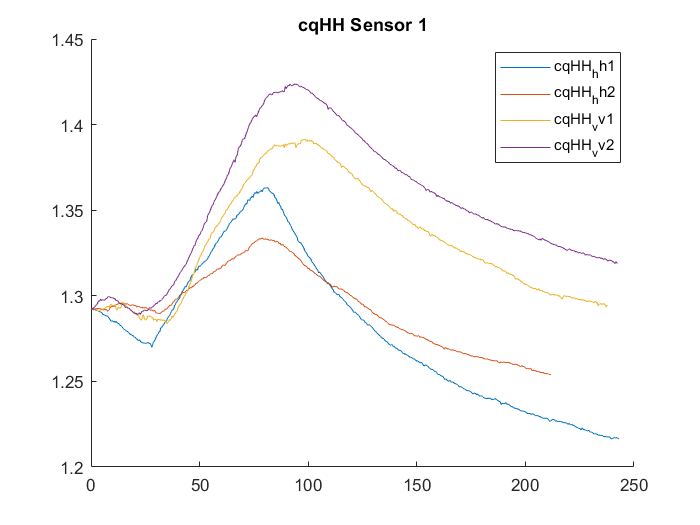

close
figure(11)
hold on;
plot(cqHH_hh1(:,1)-cqHH_hh1(1,1),cqHH_hh1(:,2)-(cqHH_hh1(1,2)-cqHH_hh2(1,2)))
plot(cqHH_hh2(:,1)-cqHH_hh2(1,1),cqHH_hh2(:,2))
plot(cqHH_vv1(:,1)-cqHH_vv1(1,1),cqHH_vv1(:,2)-(cqHH_vv1(1,2)-cqHH_hh2(1,2)))
plot(cqHH_vv2(:,1)-cqHH_vv2(1,1),cqHH_vv2(:,2)-(cqHH_vv2(1,2)-cqHH_hh2(1,2)))
hold off;
title('cqHH Sensor 1')
legend('cqHH_hh1','cqHH_hh2','cqHH_vv1','cqHH_vv2')

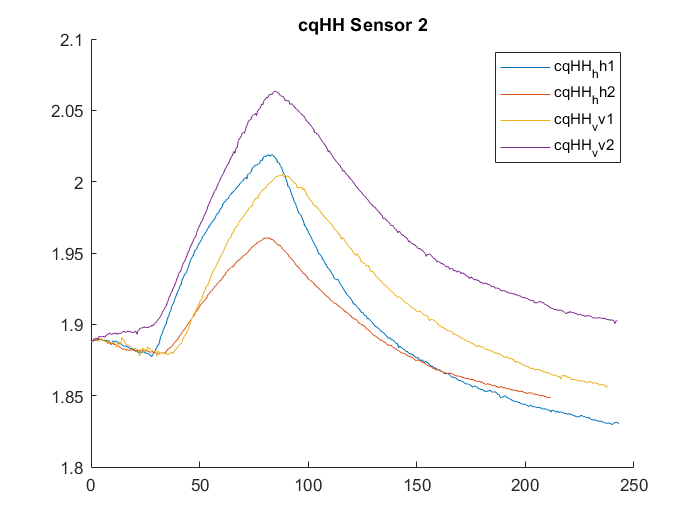

figure(12)
hold on;
plot(cqHH_hh1(:,1)-cqHH_hh1(1,1),cqHH_hh1(:,3)-(cqHH_hh1(1,3)-cqHH_hh2(1,3)))
plot(cqHH_hh2(:,1)-cqHH_hh2(1,1),cqHH_hh2(:,3))
plot(cqHH_vv1(:,1)-cqHH_vv1(1,1),cqHH_vv1(:,3)-(cqHH_vv1(1,3)-cqHH_hh2(1,3)))
plot(cqHH_vv2(:,1)-cqHH_vv2(1,1),cqHH_vv2(:,3)-(cqHH_vv2(1,3)-cqHH_hh2(1,3)))
hold off;
title('cqHH Sensor 2')
legend('cqHH_hh1','cqHH_hh2','cqHH_vv1','cqHH_vv2')

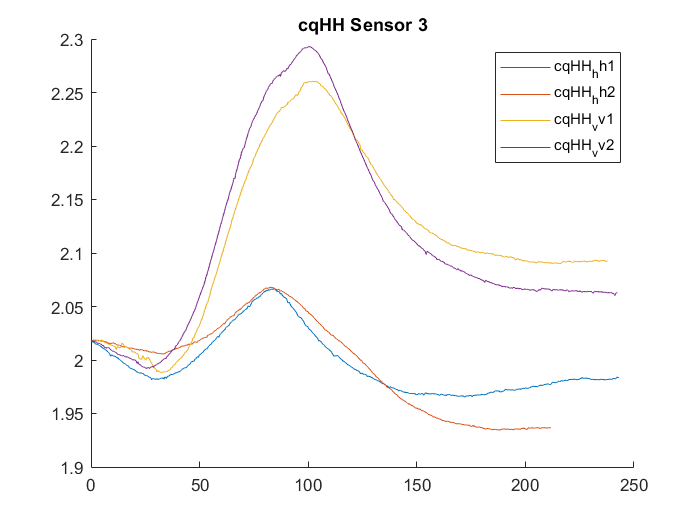

figure(13)
hold on;
plot(cqHH_hh1(:,1)-cqHH_hh1(1,1),cqHH_hh1(:,4)-(cqHH_hh1(1,4)-cqHH_hh2(1,4)))
plot(cqHH_hh2(:,1)-cqHH_hh2(1,1),cqHH_hh2(:,4))
plot(cqHH_vv1(:,1)-cqHH_vv1(1,1),cqHH_vv1(:,4)-(cqHH_vv1(1,4)-cqHH_hh2(1,4)))
plot(cqHH_vv2(:,1)-cqHH_vv2(1,1),cqHH_vv2(:,4)-(cqHH_vv2(1,4)-cqHH_hh2(1,4)))
hold off;
title('cqHH Sensor 3')
legend('cqHH_hh1','cqHH_hh2','cqHH_vv1','cqHH_vv2')

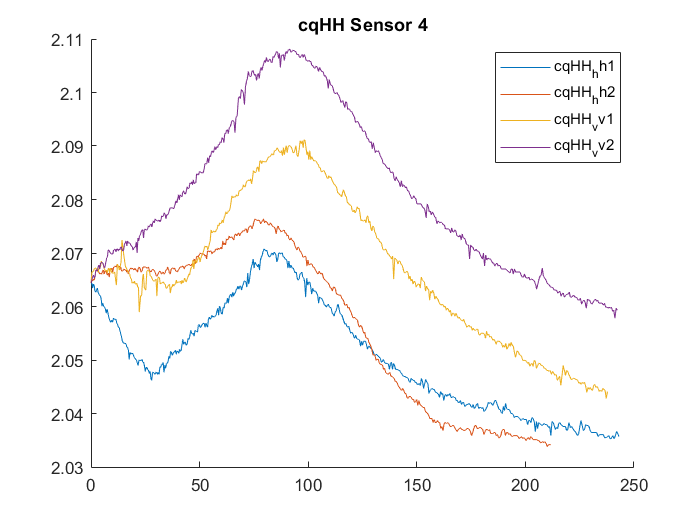

figure(14)
hold on;
plot(cqHH_hh1(:,1)-cqHH_hh1(1,1),cqHH_hh1(:,5)-(cqHH_hh1(1,5)-cqHH_hh2(1,5)))
plot(cqHH_hh2(:,1)-cqHH_hh2(1,1),cqHH_hh2(:,5))
plot(cqHH_vv1(:,1)-cqHH_vv1(1,1),cqHH_vv1(:,5)-(cqHH_vv1(1,5)-cqHH_hh2(1,5)))
plot(cqHH_vv2(:,1)-cqHH_vv2(1,1),cqHH_vv2(:,5)-(cqHH_vv2(1,5)-cqHH_hh2(1,5)))
hold off;
title('cqHH Sensor 4')
legend('cqHH_hh1','cqHH_hh2','cqHH_vv1','cqHH_vv2')

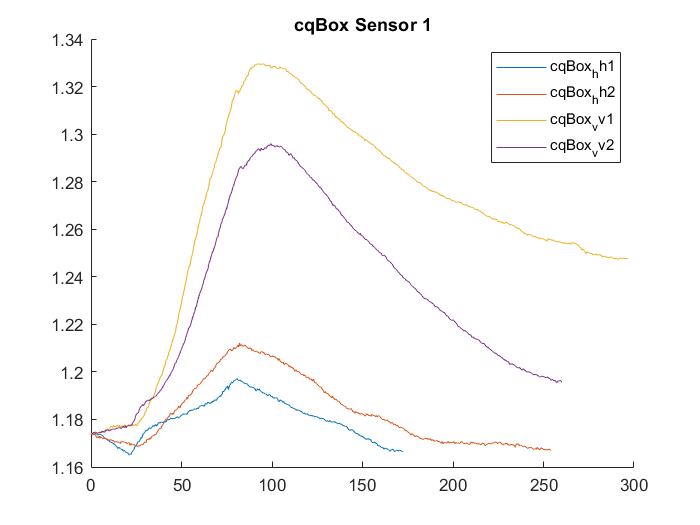

figure(15)
hold on;
plot(cqBox_hh1(:,1)-cqBox_hh1(1,1),cqBox_hh1(:,2)-(cqBox_hh1(1,2)-cqBox_hh2(1,2)))
plot(cqBox_hh2(:,1)-cqBox_hh2(1,1),cqBox_hh2(:,2))
plot(cqBox_vv1(:,1)-cqBox_vv1(1,1),cqBox_vv1(:,2)-(cqBox_vv1(1,2)-cqBox_hh2(1,2)))
plot(cqBox_vv2(:,1)-cqBox_vv2(1,1),cqBox_vv2(:,2)-(cqBox_vv2(1,2)-cqBox_hh2(1,2)))
hold off;
title('cqBox Sensor 1')
legend('cqBox_hh1','cqBox_hh2','cqBox_vv1','cqBox_vv2')

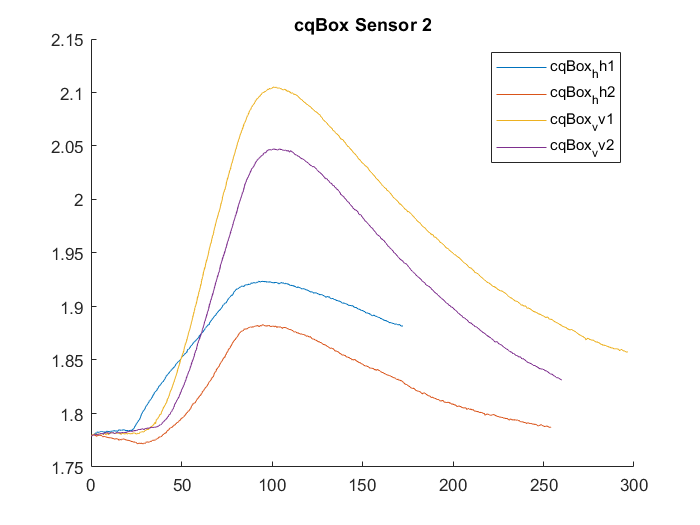

figure(16)
hold on;
plot(cqBox_hh1(:,1)-cqBox_hh1(1,1),cqBox_hh1(:,3)-(cqBox_hh1(1,3)-cqBox_hh2(1,3)))
plot(cqBox_hh2(:,1)-cqBox_hh2(1,1),cqBox_hh2(:,3))
plot(cqBox_vv1(:,1)-cqBox_vv1(1,1),cqBox_vv1(:,3)-(cqBox_vv1(1,3)-cqBox_hh2(1,3)))
plot(cqBox_vv2(:,1)-cqBox_vv2(1,1),cqBox_vv2(:,3)-(cqBox_vv2(1,3)-cqBox_hh2(1,3)))
hold off;
title('cqBox Sensor 2')
legend('cqBox_hh1','cqBox_hh2','cqBox_vv1','cqBox_vv2')

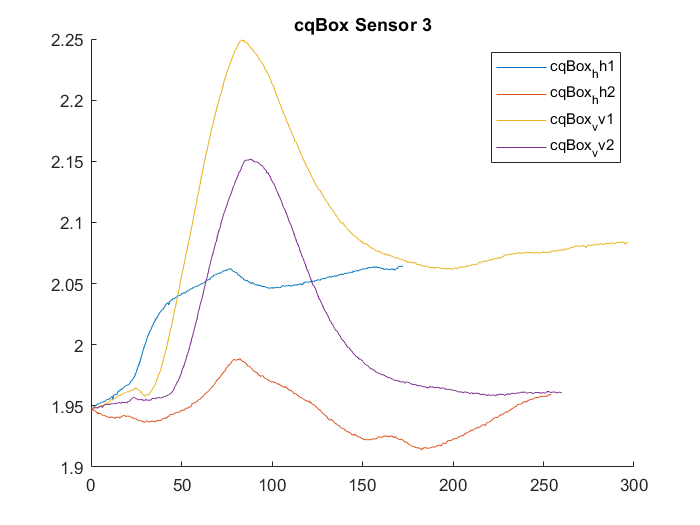

figure(17)
hold on;
plot(cqBox_hh1(:,1)-cqBox_hh1(1,1),cqBox_hh1(:,4)-(cqBox_hh1(1,4)-cqBox_hh2(1,4)))
plot(cqBox_hh2(:,1)-cqBox_hh2(1,1),cqBox_hh2(:,4))
plot(cqBox_vv1(:,1)-cqBox_vv1(1,1),cqBox_vv1(:,4)-(cqBox_vv1(1,4)-cqBox_hh2(1,4)))
plot(cqBox_vv2(:,1)-cqBox_vv2(1,1),cqBox_vv2(:,4)-(cqBox_vv2(1,4)-cqBox_hh2(1,4)))
hold off;
title('cqBox Sensor 3')
legend('cqBox_hh1','cqBox_hh2','cqBox_vv1','cqBox_vv2')

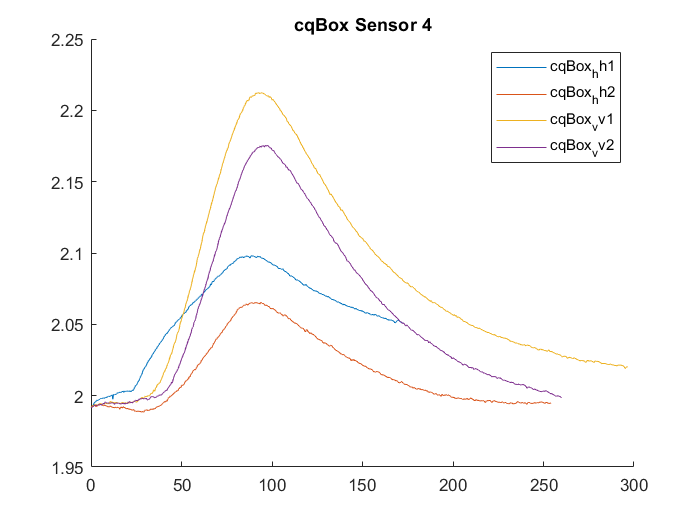

figure(18)
hold on;
plot(cqBox_hh1(:,1)-cqBox_hh1(1,1),cqBox_hh1(:,5)-(cqBox_hh1(1,5)-cqBox_hh2(1,5)))
plot(cqBox_hh2(:,1)-cqBox_hh2(1,1),cqBox_hh2(:,5))
plot(cqBox_vv1(:,1)-cqBox_vv1(1,1),cqBox_vv1(:,5)-(cqBox_vv1(1,5)-cqBox_hh2(1,5)))
plot(cqBox_vv2(:,1)-cqBox_vv2(1,1),cqBox_vv2(:,5)-(cqBox_vv2(1,5)-cqBox_hh2(1,5)))
hold off;
title('cqBox Sensor 4')
legend('cqBox_hh1','cqBox_hh2','cqBox_vv1','cqBox_vv2')